% Function to compute R-squared
function R_squared = compute_rsquare(y_actual, y_pred)
    % Ensure input vectors are column vectors
    y_actual = y_actual(:);
    y_pred = y_pred(:);
    
    % Compute SSE (Sum of Squared Errors)
    SSE = sum((y_actual - y_pred).^2);
    
    % Compute SStot (Total Sum of Squares)
    SS_tot = sum((y_actual - mean(y_actual)).^2);
    
    % Compute R-squared
    R_squared = 1 - (SSE / SS_tot);
end

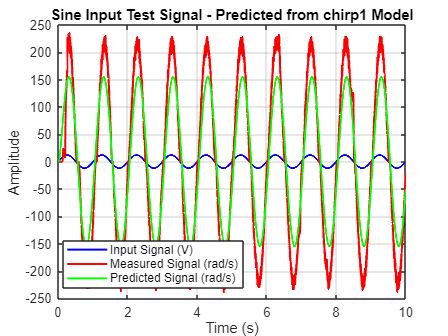

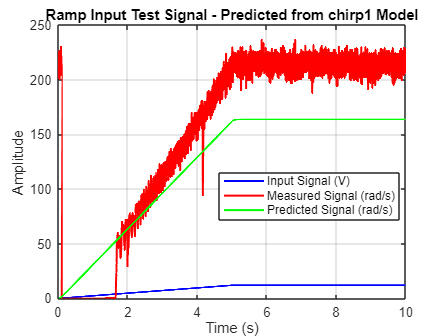

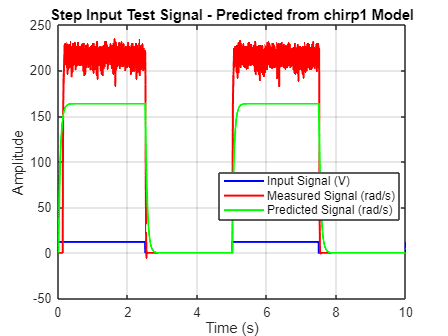

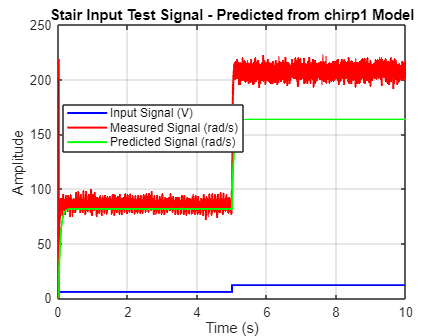

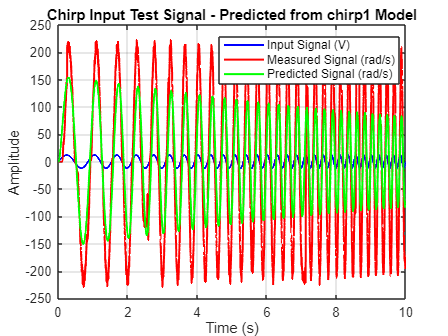

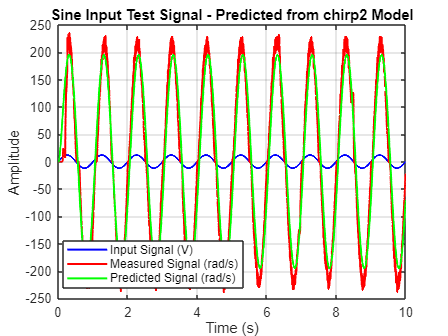

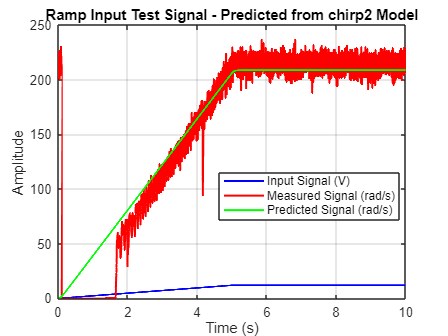

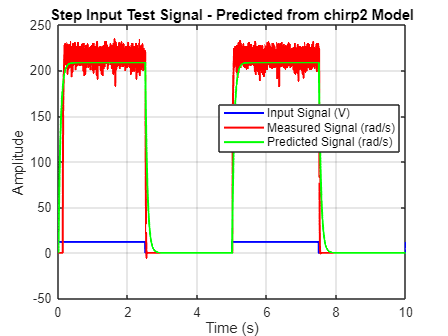

% Define test signal names
% Test_signal_names = {'Sine', 'Ramp', 'Step', 'Stair', 'Chirp'};

% Get a list of all prediction files in the "model_predict" folder
prediction_files = dir('model_predict\predict_*.mat');

% Initialize a table to store R-squared values
num_models = length(prediction_files);
num_signals = length(Test_signal_names);
R_squared_table = zeros(num_models, num_signals);
model_names = strings(num_models, 1);

% Loop through each predicted signal file
for file_idx = 1:num_models
    % Extract the file name and load the data
    file_name = prediction_files(file_idx).name;
    model_name = erase(file_name, {'predict_', '.mat'}); % Remove prefixes
    model_names(file_idx) = model_name; % Store model name
    
    % Load the predicted data
    load(fullfile('model_predict', file_name));
    
    % Extract model predictions (assuming 5 columns in the .mat file)
    model_predict_signals = {data.Data(:, 1), data.Data(:, 2), data.Data(:, 3), data.Data(:, 4), data.Data(:, 5)};
    
    % Loop through each test signal and plot with model predictions
    for i = 1:num_signals
        figure('Name', [Test_signal_names{i}, ' Comparison']);
        
        % Plot Input Test Signal
        plot(TimeArr, Inp_test_signals{i}, 'Color', 'b', 'LineWidth', 1.5);
        hold on;
        
        % Plot Measured Signal
        plot(TimeArr, Measure_test_signals{i}, 'Color', 'r', 'LineWidth', 1.5);
        
        % Plot Model Predicted Signal
        plot(TimeArr, model_predict_signals{i}, 'Color', 'g', 'LineWidth', 1.5);
        
        % Add Title and Legend
        title([Test_signal_names{i}, ' Input Test Signal - Predicted from ', model_name, ' Model']);
        legend('Input Signal (V)', 'Measured Signal (rad/s)', 'Predicted Signal (rad/s)', 'Location', 'best');
        xlabel('Time (s)');
        ylabel('Amplitude');
        grid on;
        hold off;
        
        % Save the graph in the "Validate_result" folder with the format "m_MODEL-t_TEST"
        save_path = fullfile('Validate_result', ['m_' model_name, '-t_', Test_signal_names{i}, '.png']);
        saveas(gcf, save_path);
    end
    
    % Compute R-squared for each test signal
    for i = 1:num_signals
        R_squared_table(file_idx, i) = compute_rsquare(Measure_test_signals{i}, model_predict_signals{i});
    end
end

% Create a table with labeled rows and columns for R-squared values
R_squared_table_t = array2table(R_squared_table, 'RowNames', model_names, 'VariableNames', Test_signal_names);

% Display the R-squared table with labels
disp('R-squared values for each model and test signal:');

R-squared values for each model and test signal:


disp(R_squared_table_t);

                  Sine       Ramp        Step       Stair       Chirp  
                ________    _______    ________    ________    ________

    chirp1       0.89635    0.67238      0.8614     0.70806     0.73206
    chirp2       0.94586    0.88353     0.96069      0.9366     0.77574
    chirp3       0.90876    0.72012      0.8831     0.77222     0.74748
    pulse0d1     0.64671    0.88781     0.90713     0.92338     0.37472
    pulse1d0     0.86723    0.87747     0.94494     0.93812     0.60356
    pulse2d0     0.92853    0.88053     0.95606     0.94267     0.72695
    ramp1d2     0.018278    0.23634    -0.15933    0.049179    0.014784
    ramp2d4     0.083725    0.80884     0.347


excel_filename = 'R_squared_results.xlsx';
writetable(R_squared_table_t, excel_filename, 'WriteRowNames', true);